# 实验二

**一、实验目的**

- 了解直方图的性质和应用，理解图像二值化的原理并掌握其算法实现；

- 掌握直方图均衡化、规定化算法的原理及实现；

- 了解自适应直方图均衡化算法及其应用。

**二、实验内容**

- 利用直方图特性人工选择阈值对图像进行二值化，同屏显示原图、原图直方图和二值化后图像，测试图像分别为eight.tif、rice.png和Fig0338(a)(blurry_moon)  (图像文件见QQ群)；

- 查询graythresh函数的功能与用法，了解Otsu 阈值选择算法，使用graythresh函数计算eight.tif、rice.png和Fig0338(a)(blurry_moon)三幅图像的最佳阈值并对图像进行二值化，在此基础上，与自己实验内容1人工选择的阈值作对比；

- 在Matlab中编程实现直方图均衡化算法（不能使用histeq函数，自己编程实现其功能，使用图像pout.tif）；

- 自学直方图规定化算法，使用histeq函数对pout.tif图像进行直方图规定化（指定的直方图为Fig0809(a)图像的直方图），同屏显示处理前后的图像及其对应的直方图和算法中指定的直方图；

- 了解自适应直方图均衡化算法，查询Matlab中对应的函数，并使用该函数对图像进行自适应直方图均衡化，同屏显示处理前后的图像及其对应的直方图。

## 任务1

第一步 : 图像导入；

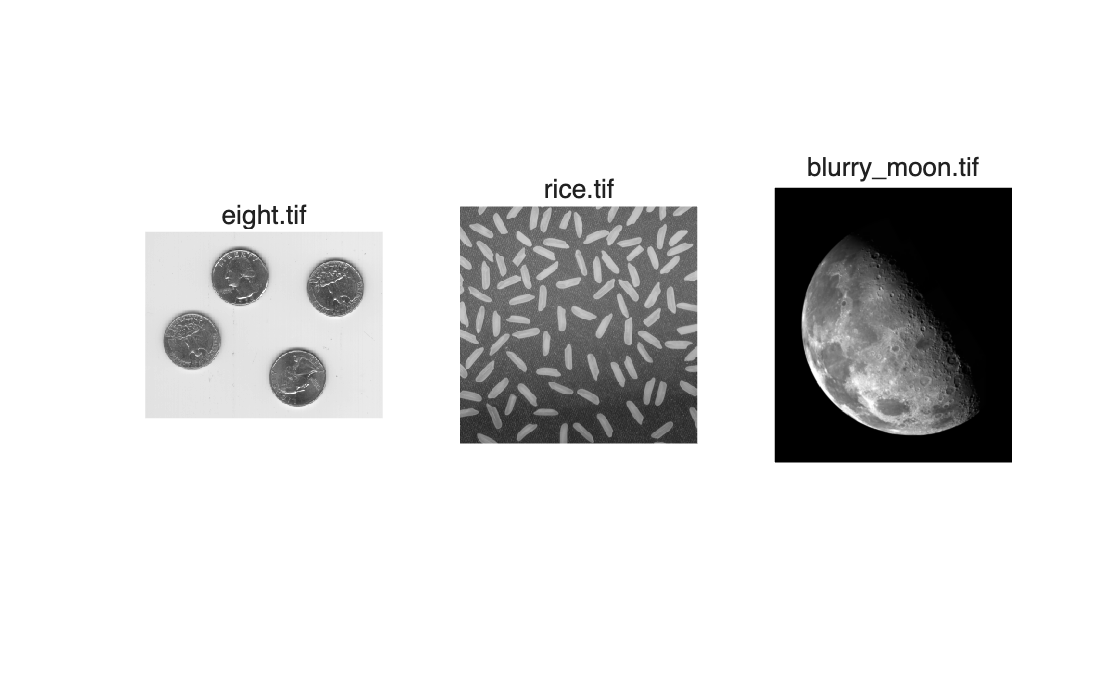

I_eight = imread("eight.tif");
I_rice = imread("rice.png");
I_moon = imread("/Users/billow.yi.c/Documents/raw/DIP3E_Original_Images_CH03/Fig0338(a)(blurry_moon).tif");
figure
subplot(1,3,1);
imshow(I_eight);
title("eight.tif");
subplot(1,3,2);
imshow(I_rice);
title("rice.tif")
subplot(1,3,3);
imshow(I_moon);
title("blurry\_moon.tif")

第二步：定义直方图函数

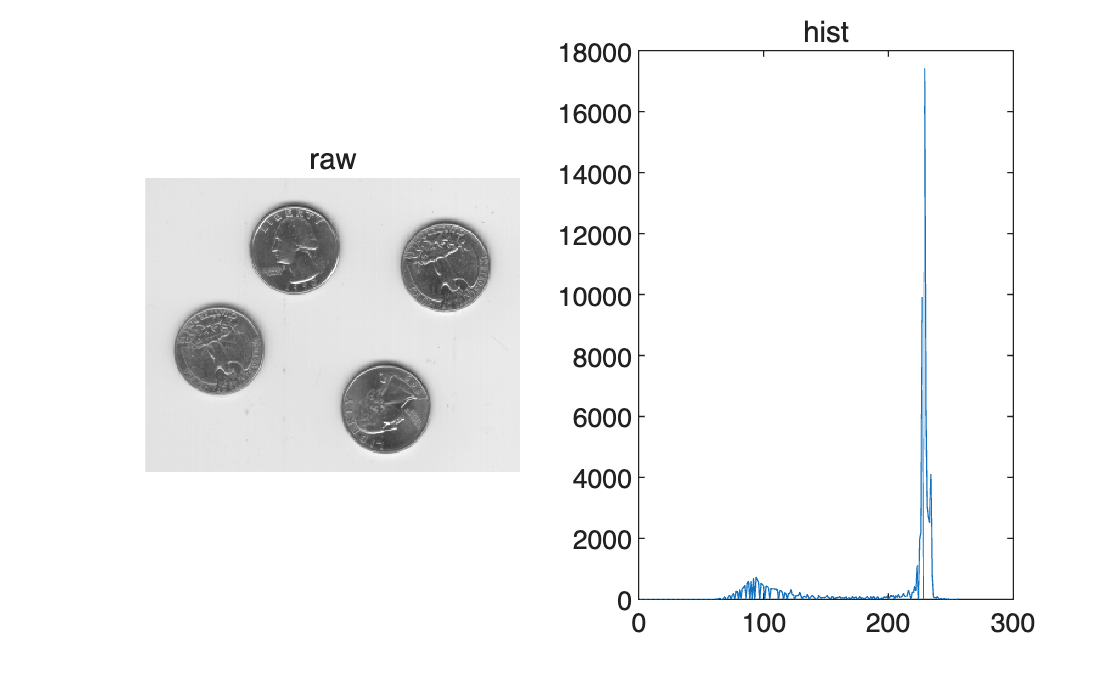

function hist = histGeneration(img)

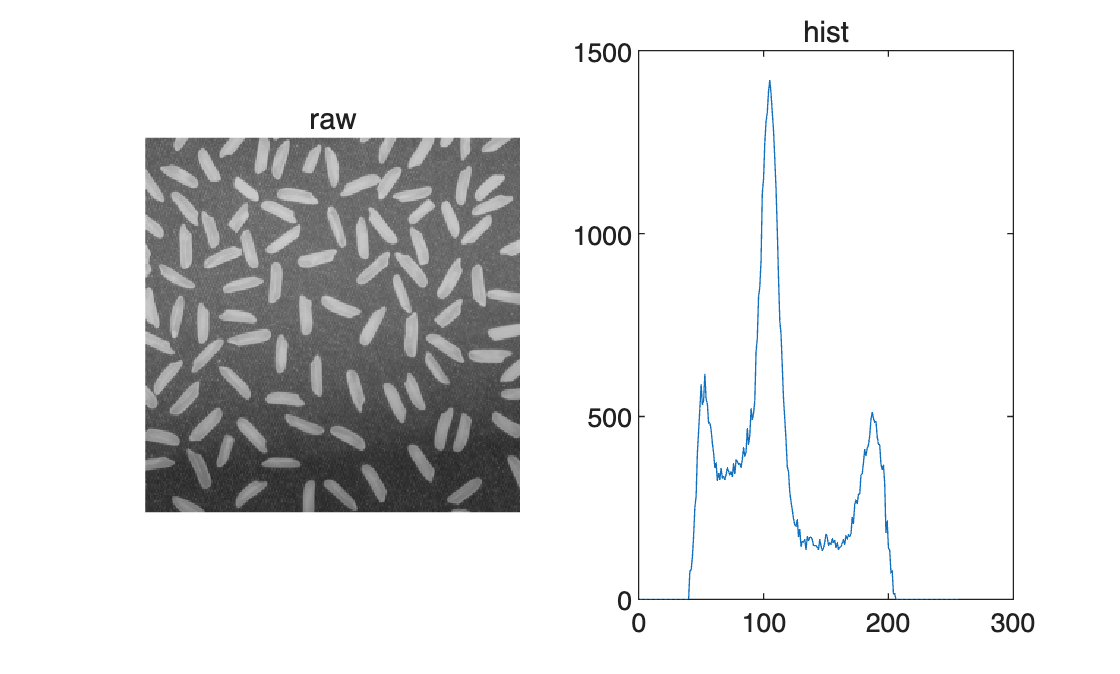

    hist = imhist(img);

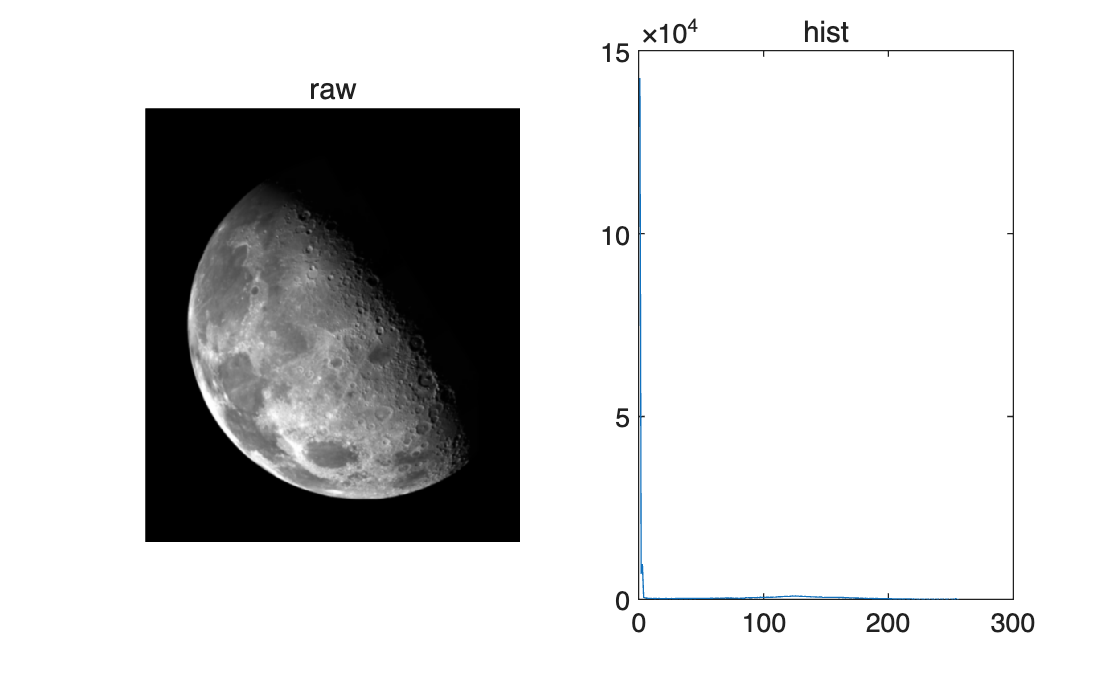

    figure

    subplot(1,2,1);
    imshow(img);
    title("raw");
    subplot(1,2,2);
    plot(hist);
    title("hist")
end

第三步：开始处理

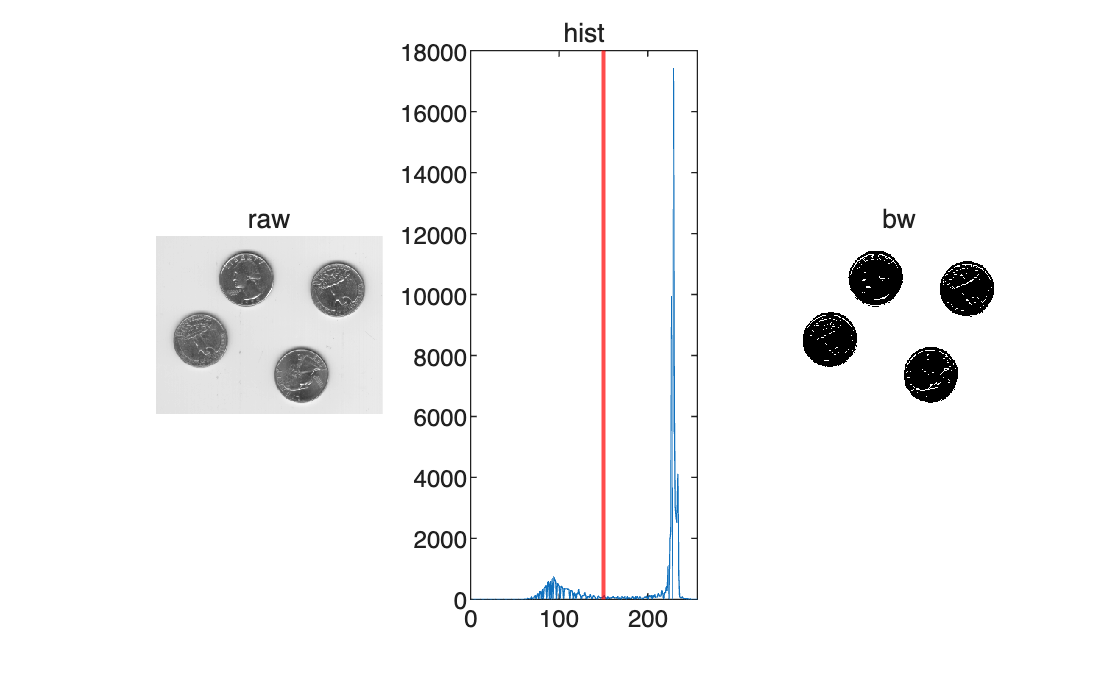

hist_eight = histGeneration(I_eight);

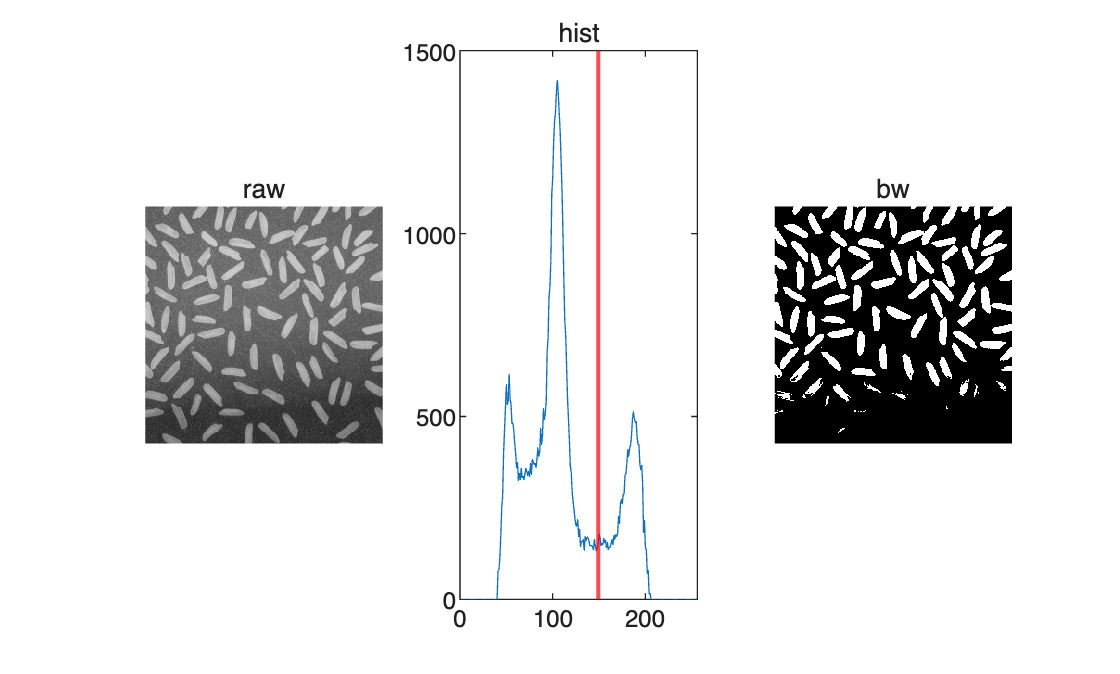

hist_rice = histGeneration(I_rice);

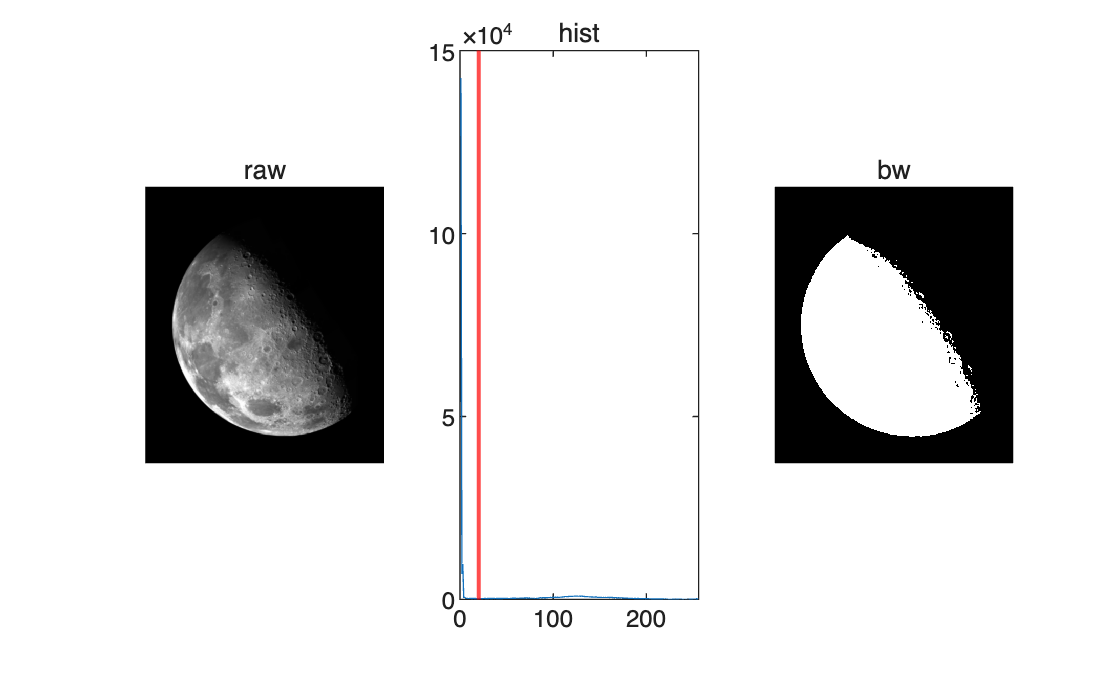

hist_moon = histGeneration(I_moon);

第四步：定义完整函数

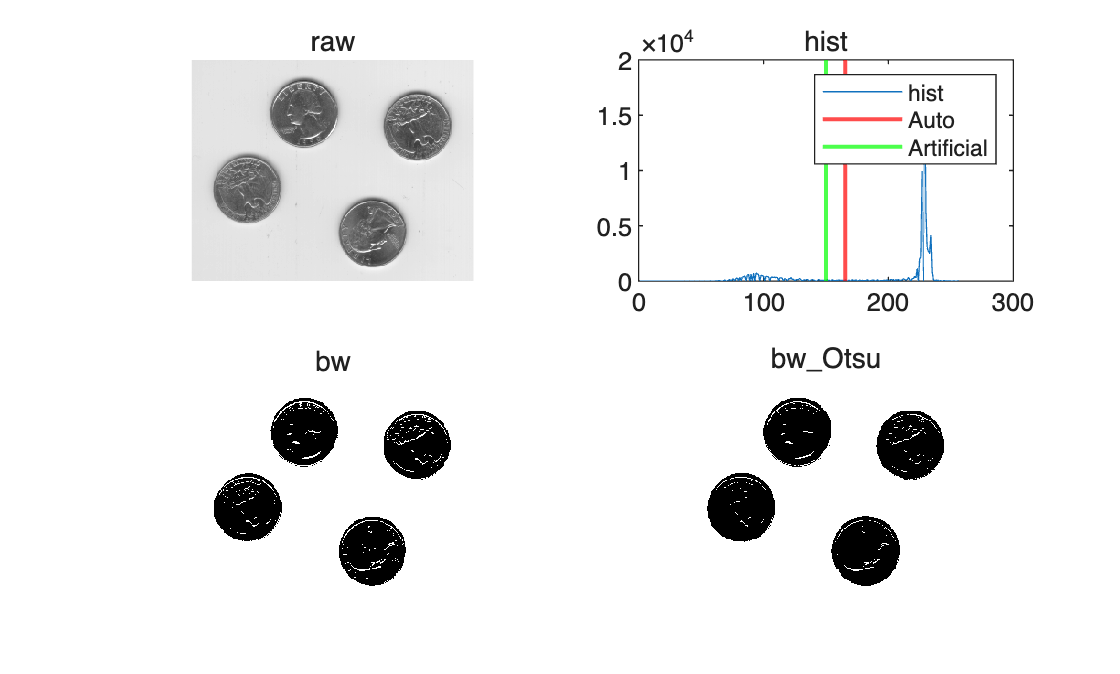

function img_bw = bwGeneration(img,n)

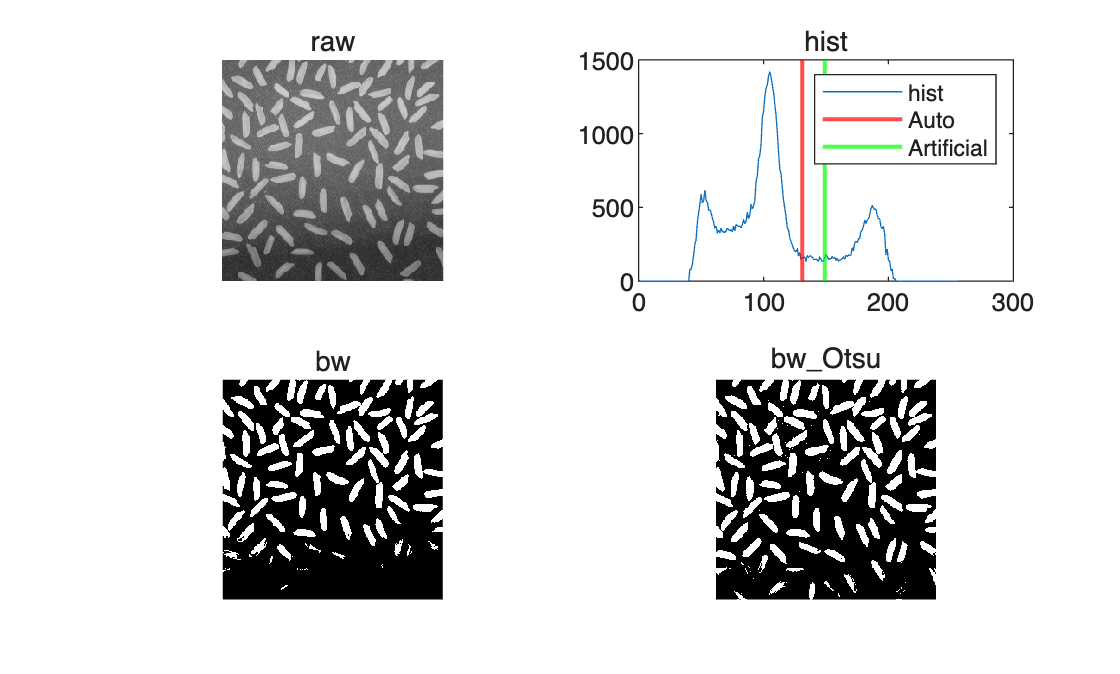

    n2one = n/255;

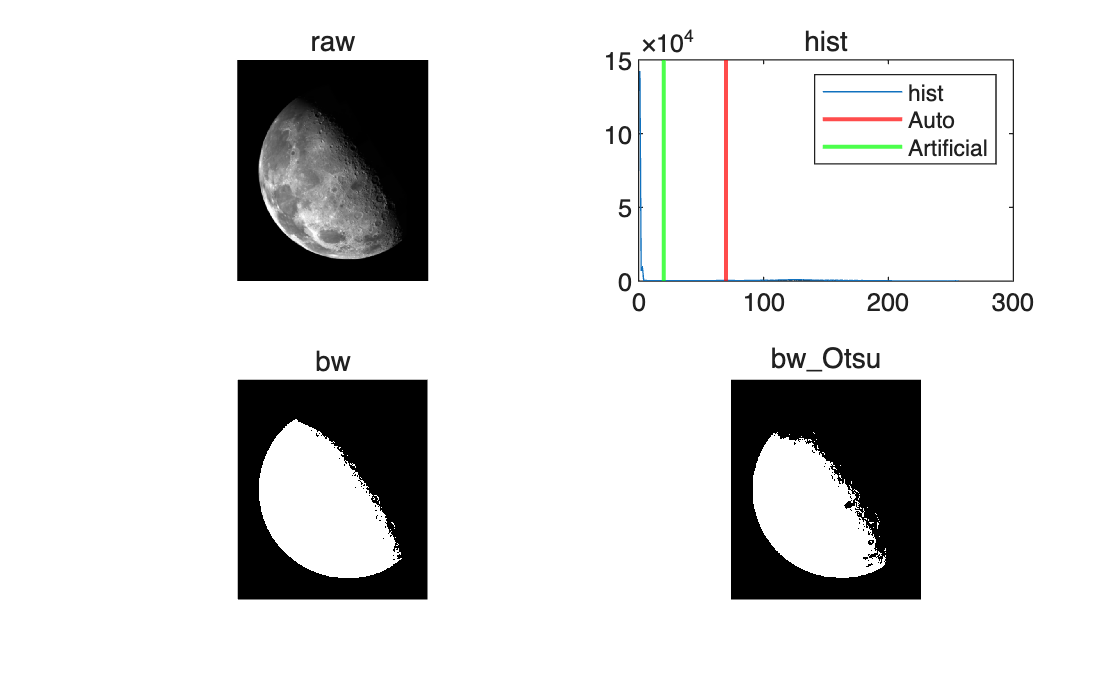

    img_bw = im2bw(img,n2one);

    hist = imhist(img);
    figure
    subplot(1,3,1);
    imshow(img);
    title("raw");
    subplot(1,3,2);
    plot(hist);
    title("hist")
    hold on;
    xline(n, 'r-', 'LineWidth', 1.5);
    hold off;
    subplot(1,3,3);
    imshow(img_bw);
    title("bw");
end

第五步：最终输出

bw_eight = bwGeneration(I_eight,150);
bw_rice = bwGeneration(I_rice,149);
bw_moon = bwGeneration(I_moon,20);

## 任务2

第一步：定义Otsu算法函数集

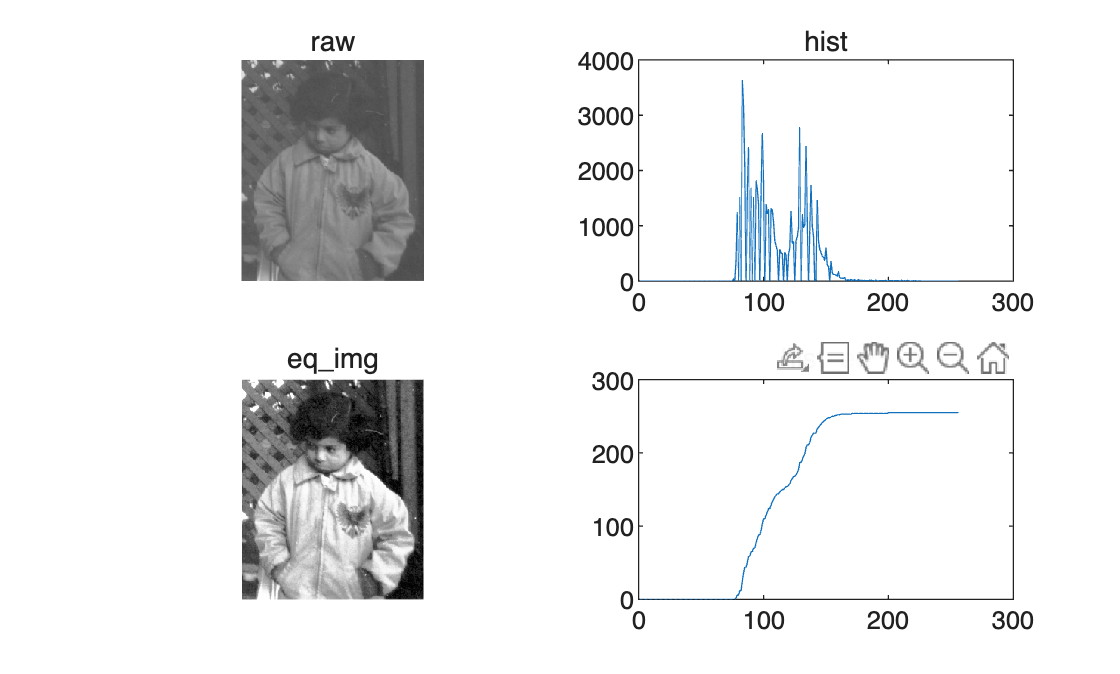

function BW = bwGenerationSmart(img,n,bw)
    level = graythresh(img);
    hist = imhist(img);
    BW = imbinarize(img, level);
    figure
    subplot(2,2,1);
    imshow(img);
    title("raw");
    subplot(2,2,2);
    plot(hist);
    title("hist")
    hold on;

    xline(level*255, 'r-', 'LineWidth', 1.5);
    xline(n, 'g-', 'LineWidth', 1.5);
    legend("hist","Auto","Artificial");
    hold off;
    subplot(2,2,3);
    imshow(bw);
    title("bw");
    subplot(2,2,4);
    imshow(BW);
    title("bw\_Otsu");
end

第二步：运行函数

BW_eight = bwGenerationSmart(I_eight,150,bw_eight);
BW_rice = bwGenerationSmart(I_rice,149,bw_rice);
BW_moon = bwGenerationSmart(I_moon,20,bw_moon);

## 任务3

第一步：定义均衡函数

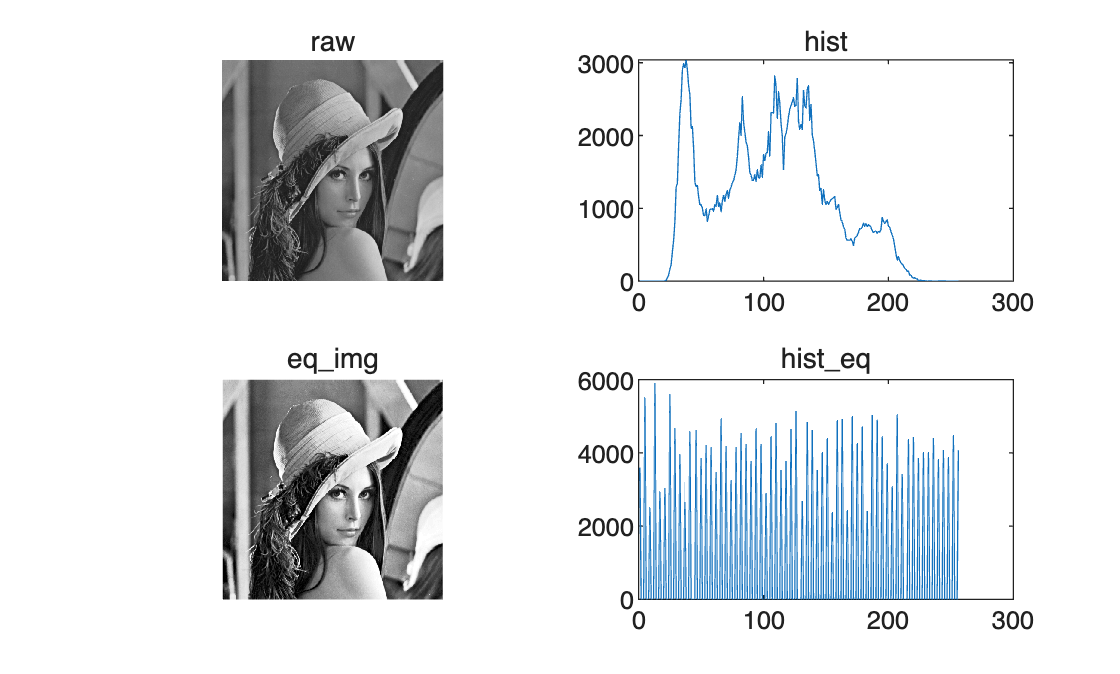

function [out,grey_s,hist] = histeqSelf(img)
    [x_size, y_size] = size(img);
    N = x_size * y_size;
    hist = imhist(img);

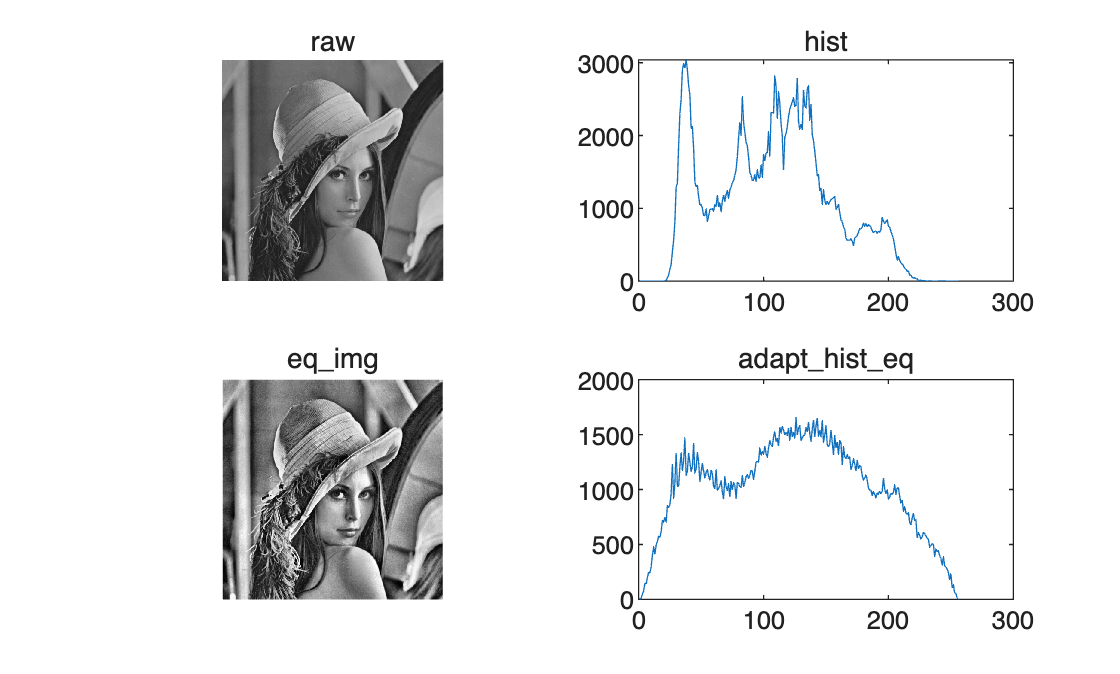

    pr = zeros(256, 1);
    temp = 0;
    grey_s = zeros(256, 1);

    for i = 1:256
        temp = temp + hist(i);
        pr(i) = temp / N;
        grey_s(i) = round(255 * pr(i));
    end
    
    out = zeros(x_size, y_size, 'uint8');
    for i = 1:x_size
        for j = 1:y_size
            original_gray = img(i, j);
            out(i, j) = grey_s(original_gray + 1);
        end
    end

end

第二步：对图像处理

I_pout = imread("pout.tif");
[eq_pout,eqhist_pout,hist_pout] = histeqSelf(I_pout);
figure
subplot(2,2,1);
imshow(I_pout);
title("raw");
subplot(2,2,2);
plot(hist_pout);
title("hist");
subplot(2,2,4);
plot(eqhist_pout);
title("hist\_eq");
subplot(2,2,3);
imshow(eq_pout);
title("eq\_img");

I_0809 = imread("/Users/billow.yi.c/Documents/raw/DIP3E_CH08_Original_Images/Fig0809(a).tif");
eq_0809= histeq(I_0809);
hist_0809 = imhist(I_0809);
eqhist_0809 = imhist(eq_0809);
figure
subplot(2,2,1);
imshow(I_0809);
title("raw");
subplot(2,2,2);
plot(hist_0809);
title("hist");
subplot(2,2,4);
plot(eqhist_0809);
title("hist\_eq");
subplot(2,2,3);
imshow(eq_0809);
title("eq\_img");

eq_08091= adapthisteq(I_0809);
hist_08091 = imhist(I_0809);
eqhist_08091 = imhist(eq_08091);
figure
subplot(2,2,1);
imshow(I_0809);
title("raw");
subplot(2,2,2);
plot(hist_08091);
title("hist");
subplot(2,2,4);
plot(eqhist_08091);
title("adapt\_hist\_eq");
subplot(2,2,3);
imshow(eq_08091);
title("eq\_img");